# Elektrik Makineleri Asenkron Motor Hesaplayıcısı

**Ozan Emre Eren 2020**

**Use it at your own risk !!!**

**Parametreler:**

Vt=380/2; % Faz-Faz Gerilimi
pf=0.85; % Güç faktörü cos(q)
Vphi=Vt/sqrt(3)

Vphi = 109.6966

f=50; % Frekans
pole=4; % Pol sayısı
R1=0.4; % R1
R2=0.3; % R2
X1=0.4/2; % R3
X2=0.3/2; % R4
XM=21/2; % XM
s=0.06; % Slip (s)
% nsync=; % Senkron hız
%  nm=; % Anlık hız

**Thevenin Hesaplamaları**

$V_{\textrm{TH}} =V_{\phi } \frac{X_M }{\sqrt{{R_1 }^2 +{\left(X_1 +X_M \right)}^2 }}$     ,     $R_{\textrm{TH}} =R_1 {\left(\frac{X_M }{X_1 +X_M }\right)}^2$     ,     $X_{\textrm{TH}} =X_1$

Vth=Vphi*((XM)/(sqrt(R1^2+(X1+XM)^2)))

Vth = 107.5710

Rth=R1*((XM)/(X1+XM))^2

Rth = 0.3852

Xth=X1

Xth = 0.2000

**Kayma (s) ve Hız Hesaplamaları**

$n_{\textrm{sync}} =\frac{120\ldotp f_e }{P}$     ,     $s=\frac{n_{\textrm{sync}} -n_m }{n_{\textrm{sync}} }$     ,     $s_{\max } =\frac{R_2 }{\sqrt{{R_{\textrm{TH}} }^2 +{\left(X_{\textrm{TH}} +X_2 \right)}^2 }}$     ,     $n_m =\left(1-s\right)\ldotp n_{\textrm{sync}}$     ,     $w_{\textrm{sync}} =\frac{2\ldotp \pi \ldotp n_s }{60}$      ,     $w_m =\frac{2\ldotp \pi \ldotp n_m }{60}$             

nsync=(120*f)/pole % Senkronize hız

nsync = 750

%s=(nsync-nm)/nsync;
smax=R2/(sqrt(Rth^2+(Xth+X2)^2)) % Maksimum 's'

smax = 0.5764

nm=(1-s)*nsync % Belirli 's' değerindeki hız

nm = 705

nmax=(1-smax)*nsync % Maksimum hız

nmax = 317.6821

Nmaksimummoment=(1-smax)*nsync % Maksimum Momentumdaki Hız

Nmaksimummoment = 317.6821

wsync=(2*pi*nsync)/60;
%wm=(2*pi*nm)/60;

**Tork (**$\tau$**) Hesaplamaları**

$\tau_{\max } =\frac{3\ldotp {V_{\textrm{TH}} }^2 }{2\ldotp w_{\textrm{sync}} \ldotp \left\lbrack {R_{\textrm{TH}} }^2 +\sqrt{{R_{\textrm{TH}} }^2 +{\left(X_{\textrm{TH}} +X_2 \right)}^2 }\right\rbrack }$     ,     $\tau_{\textrm{start}} =\frac{3\ldotp {V_{\textrm{TH}} }^2 \ldotp \left(\frac{R_2 }{s}\right)}{w_{\textrm{sync}} \ldotp \left\lbrack {\left(R_{\textrm{TH}} +\left(\frac{R_2 }{s}\right)\right)}^2 +{\left(X_{\textrm{TH}} +X_2 \right)}^2 \right\rbrack }$     

Tmax=(3*Vth^2)/(2*wsync*(Rth+sqrt(Rth^2+(Xth+X2)^2)))

Tmax = 244.0269

Tstart=(3*Vth^2*(R2/1))/(wsync*((Rth+(R2/1))^2+(Xth+X2)^2))

Tstart = 223.9936

Tind=(3*Vth^2*(R2/s))/(wsync*((Rth+(R2/s))^2+(Xth+X2)^2)) % Belirtilen 's' değerindeki tork

Tind = 75.8857

**Güç Hesaplamaları**

$I_1 =\frac{V_{\phi } }{Z_{\textrm{eq}} }$     ,     $P_{\textrm{SCL}} =3\ldotp {I_1 }^2 \ldotp R_1$     ,     $P_{\textrm{AG}} =P_{\textrm{in}} -P_{\textrm{SCL}} -P_{\textrm{Core}}$     ,     $P_{\textrm{AG}} =3\ldotp {I_2 }^2 \ldotp \frac{R_2 }{s}$     ,     $P_{\textrm{RCL}} =3\ldotp {I_2 }^2 \ldotp R_2$     ,     $P_{\textrm{Core}} =3\ldotp {E_1 }^2 \ldotp G_c$     ,     $P_{\textrm{Conv}} =P_{\textrm{AG}} -P_{\textrm{RCL}}$        $P_{\textrm{Conv}} =3\ldotp {I_2 }^2 \ldotp R_2 \ldotp \left(\frac{1-s}{s}\right)$     ,     $P_{\textrm{Conv}} =\left(1-s\right)\ldotp P_{\textrm{AG}}$

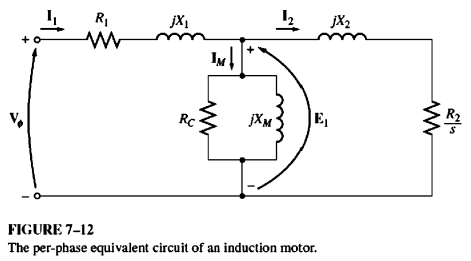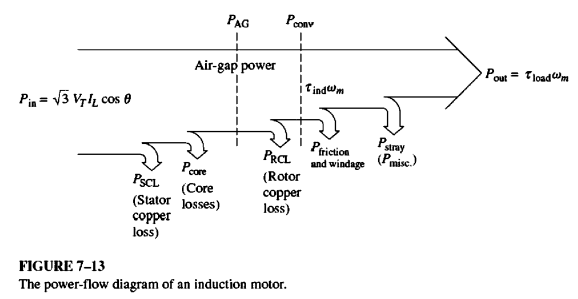

%Zeq Calculations
Z2=(R2/s)+1i*X2;
Zf=(Z2*(1i*XM))/(Z2+(1i*XM));
Zstator=R1+(1i*X1);
Zeq=Zstator+Zf

Zeq = 4.3824 + 2.2175i

%---------------------------
I1=Vphi/Zeq

I1 = 19.9286 - 10.0842i

%I1=;   % Soruda doğrudan verilirse
%---------------------------
Pin=sqrt(3)*Vt*abs(I1)*pf

Pin = 6.2476e+03

%---------------------------
Pscl=3*(abs(I1))^2*R1

Pscl = 598.6063

%Pscl=;     % Soruda doğrudan verirse
%---------------------------
%Pcore=1.8*10^3;
%---------------------------
%Prcl=1100;
%---------------------------
Pag=Pin-Pscl%-Pcore

Pag = 5.6490e+03

%---------------------------
Pconv=(1-s)*Pag

Pconv = 5.3101e+03

%Pconv=Pag-Prcl % Eğer soruda kayma(s) yerine Rotor Copper Loss verilirse bu formülü kullan
%---------------------------
Pout=Pconv%-Prcl%-Pf&w

Pout = 5.3101e+03

%---------------------------
Tind=Pag/wsync

Tind = 71.9252

%---------------------------
%Tload=Pout/wm
%---------------------------
efficiency=(Pout/Pin)*100

efficiency = 84.9935

**Çalıştırma Deneyleri**

**    DC Deneyi**

        
$$R_1 =\frac{V_{\textrm{DC}} }{2\ldotp I_{\textrm{DC}} }$$
    

    **Boşta Çalışma Deneyi**

        $I_{L,\textrm{av}} =\frac{I_A +I_B +I_C }{3}$     ,     $V_{\phi ,\textrm{nl}} =\frac{V_{\phi } }{\sqrt{3}}$     ,     $\left|Z_{\textrm{nl}} \right|=\frac{V_{\phi ,\textrm{nl}} }{I_{L,\textrm{av}} }=X_1 +X_M$

    **Tutulu Rotor Deneyi**

        $I_{L,\textrm{av}} =\frac{I_A +I_B +I_C }{3}$     ,     $\left|Z_{\textrm{LR}} \right|=\frac{V_T }{\sqrt{3}\ldotp I_A }$

% DC DENEY PARAMETRELERİ

%Vdc=;
%Idc=;
%R1=Vdc/Idc

%---------------------------

%BOŞTA ÇALIŞMA DENEY PARAMETRELERİ

%Vt1=;
%Ia1=;
%Ib1=;
%Ic1=;
%f1=;
%Pin1=;
%Ilav1=(Ia1+Ib1+Ic1)/3
%Vphi1=Vt1/sqrt(3)
%Znl=Vphi1/Ilav1

%---------------------------

%TUTULU ROTOR DENEYİ

%Vt2=;
%Ia2=;
%Ib2=;
%Ic2=;
%f2=;
%Pin2=;
%Ilav2=(Ia2+Ib2+Ic2)/3
%ZLR=Vt2/(sqrt(3)*Ilav2)
%impangle=sec(Pin2/(sqrt(3)*Vt2*Ilav2)

%---------------------------

**Tork-Hız Grafik Çizdirme**

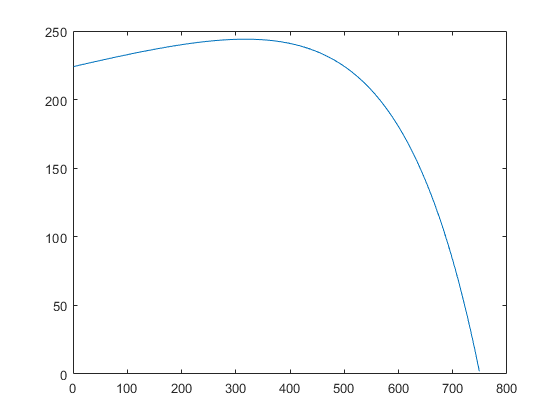

nm1=[1:1:nsync];
s1=(nsync-nm1)./nsync;
pay=(3.*Vth.^2.*(R2./s1));
payda=(wsync.*((Rth+(R2./s1)).^2+(Xth+X2).^2));
Tgraph=pay./payda;
plot(nm1,Tgraph)